#### Question 1 

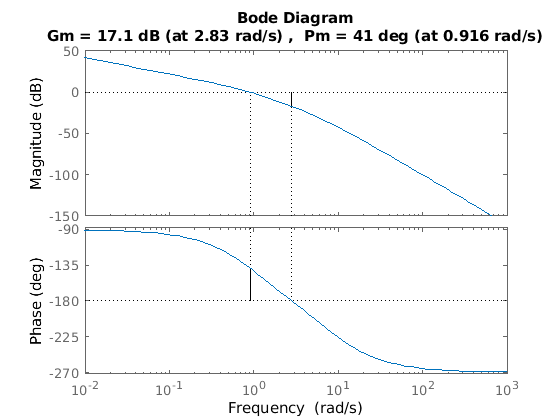

phase_crossover = 2.8284

gain_crossover = 0.9158

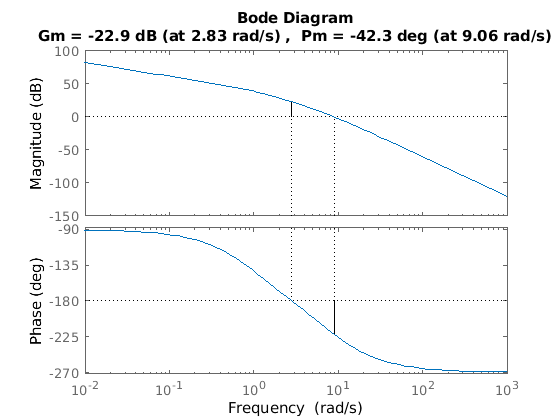

phase_crossover = 2.8284

gain_crossover = 9.0643

clear;
close all;
s = tf('s');
gain_list = [10 1000];
G = 1/(s*(s+1)*(s+8));
hold off;
for k = gain_list
    margin(k*G)
    [~,~,phase_crossover,gain_crossover] = margin(k*G)
end

#### Question 2

clear;
sympref('FloatingPointOutput',true);
syms K s w real;
G(s) = K/(s*(s^2+s+4))

$$G(s) = \frac{K}{s\,\left(s^{2}+s+4\right)}$$

H = 1

H = 1

GH=G(w*1i)*H

$$GH = -\frac{1\,K\,\mathrm{i}}{w\,\left(-w^{2}+1\,w\,\mathrm{i}+4\right)}$$

[num,den]=numden(GH);

den = expand(den);
a = real(num)

$$a = -K$$

b = imag(num)

$$b = 0$$

c = real(den)

$$c = w^{2}$$

d = imag(den)

$$d = w^{3}-4\,w$$


amp = simplify(sqrt(a^2+b^2)/sqrt(c^2+d^2))

$$amp = \frac{\left|K\right|}{\left|w\right|\,{\left(w^{4}-7\,w^{2}+16\right)}^{0.5000}}$$


phase = simplify(atan(b/a)-atan(d/c))

$$phase = -\mathrm{atan}\left(\frac{w^{2}-4}{w}\right)$$


phase_eq = phase == deg2rad(-180 + 50) + pi % the + pi here is so the eq solves between [-pi/2,pi/2]

$$phase\_eq = -\mathrm{atan}\left(\frac{w^{2}-4}{w}\right)=0.8727$$


S = eval(solve(phase_eq));

wn = S(2)

wn = 1.4910

gain_eq = subs(amp,w,wn) == 1

$$gain\_eq = 0.2891\,\left|K\right|=1$$

S = eval(solve(gain_eq));
Kn = S(2)

Kn = 3.4585


phase_crossover_eq = phase == deg2rad(-180) + pi

$$phase\_crossover\_eq = -\mathrm{atan}\left(\frac{w^{2}-4}{w}\right)=0$$

S = eval(solve(phase_crossover_eq));
phase_crossover = S(2)

phase_crossover = 2


amp

$$amp = \frac{\left|K\right|}{\left|w\right|\,{\left(w^{4}-7\,w^{2}+16\right)}^{0.5000}}$$


gain_margin = eval(subs(amp,[K, w], [Kn, phase_crossover]))

gain_margin = 0.8646


gain_margin_decibels = 20*log(gain_margin)

gain_margin_decibels = -2.9091

#### Question 3

clear;
sympref('FloatingPointOutput',true);
syms K s w real;
G1(s)= K*(s+.1)/(s+.5) 

$$G1(s) = \frac{K\,\left(s+0.1000\right)}{s+0.5000}$$

G2(s)=10/(s*(s+1))

$$G2(s) = \frac{10}{s\,\left(s+1\right)}$$

H = 1

H = 1


GH = G1(w*1i)* G2(w*1i)*H

$$GH = -\frac{10\,K\,\left(0.1000+1\,w\,\mathrm{i}\right)\,\mathrm{i}}{w\,\left(1+1\,w\,\mathrm{i}\right)\,\left(0.5000+1\,w\,\mathrm{i}\right)}$$


[num,den]=numden(GH);

den = expand(den);
a = real(num)

$$a = 20\,K\,w$$

b = imag(num)

$$b = -2\,K$$

c = real(den)

$$c = w-2\,w^{3}$$

d = imag(den)

$$d = 3\,w^{2}$$


amp = simplify(sqrt(a^2+b^2)/sqrt(c^2+d^2))

$$amp = \frac{2\,\left|K\right|\,\sqrt{100\,w^{2}+1}}{\left|w\right|\,{\left(4\,w^{4}+5\,w^{2}+1\right)}^{0.5000}}$$


phase = simplify(atan(b/a)-atan(d/c))

$$phase = \mathrm{atan}\left(\frac{3\,w}{2\,w^{2}-1}\right)-\mathrm{atan}\left(\frac{0.1000}{w}\right)$$


phase_eq = phase == deg2rad(-180 + 50) + pi % the + pi here is so the eq solves between [-pi/2,pi/2]

$$phase\_eq = \mathrm{atan}\left(\frac{3\,w}{2\,w^{2}-1}\right)-\mathrm{atan}\left(\frac{0.1000}{w}\right)=0.8727$$


S = eval(solve(phase_eq));

wn = S

wn = 1.4384

gain_eq = subs(amp,w,wn) == 1

$$gain\_eq = 3.7577\,\left|K\right|=1$$

S = eval(solve(gain_eq));
Kn = S(2)

Kn = 0.2661

Phase margin lies above phase = -180 so gain margin is infinity